# Aula 7 - Laboratório de Controle - 2021/1 

## Modelagem do motor CC e sintonia de controladores

## Nome: Yuri Rissi Negri

turma=5;
I=8;
Tempo=4;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';
M=M*fliplr(eye(5,5));
I=M(I,turma);
load dados.mat
i=I*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));
arquivo='motor_cc_R2015.slx';

## Atividade 1 - Análise dos dados do motor CC

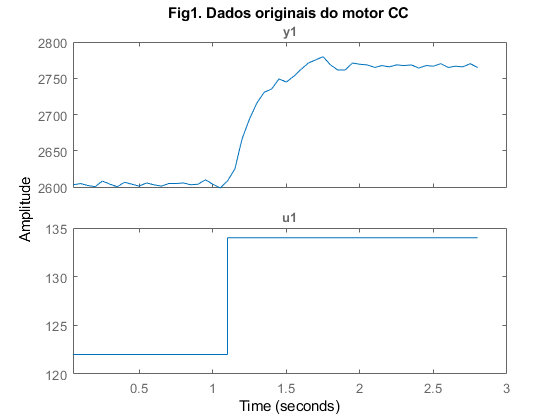

dat=iddata(y1,u1,Ts);
figure; plot(dat);title('Fig1. Dados originais do motor CC');

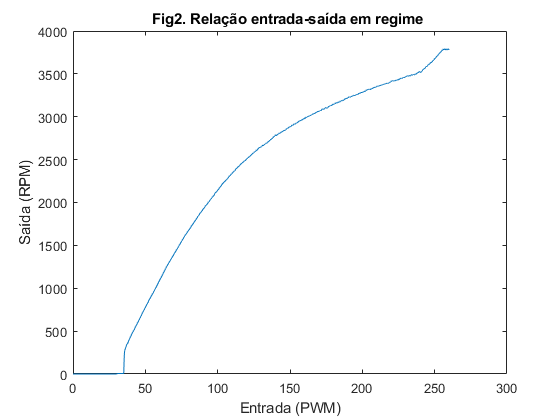

figure;plot(u2,y2);title('Fig2. Relação entrada-saída em regime ')
xlabel('Entrada (PWM)');ylabel('Saída (RPM)');

1.1 Explique o sinal aplicado e sua resposta usando a Figura 1.

    A figura 1 representa uma região de operação de uma entrada em sequência de degraus PWM (que simula uma entrada em rampa). Então, para o nosso caso, estaremos analisando apenas um degrau PWM (122 - 134) dessa sequência, e sua saída correspondente, para assim obter nosso modelo.

1.2 O que é zona morta e qual seu valor no motor utilizado? (Figura 2)

    Da figura 2, temos que até uma entrada 35 PWM nosso motor apresenta como saída zero, o que caracteriza a zona morta. Fisicamente isso pode ser explicado pelo fato de que exige um atrito a ser vencido antes do motor começar a rotacionar, e esse atrito é vencido quando se atinge um valor de tensão suficiente, que para o nosso sistema é a entrada PWM em 35.

1.3 Calcule aproximadamente o ganho do motor para rotação de 1000rpm e para a rotação de regime da figura 1 

    Para o ganho, basta fazer a variação da saída pela variação da entrada, assim em 1000rpm temos uma entrada 57 PWM, logo tomando um ponto próxmo:

K = (1100-1000)/(60-57) = 33,33

    Da figura 1, temos que a rotação em regime para nossa região é em torno de 2750, assim encontrado uma variação próxima a essa região na figura 2 temos:

K = (2750-2600)/(134-122) = 12,5

## Atividade 2 - Obtenção do modelo do motor CC

2.1 Use os dados de dat_1 e obtenha um modelo g1 de ordem 1+delay e g2 de ordem 2, escolhendo um delay que dê um bom fit para g1. Compare o fit de g1 e g2.

    Foi escolhido um deleay = 0,05, o que nos gerou um FIT de 93,19%, enquanto para g2 de ordem 2 teve um FIT 94,82% que é ligeiramente maior ao FIT de g1, fazendo com que g2 se aproximando mais da nossa curva real do motor. São boas aproximações visto que estamos lidando com um sistema real com ruído. 

2.2 Compare o ganho K obtido via g2 e o ganho K que calculou na atividade 1.3

    Na atividade 1.3 obtemos um ganho K = 12,5 enquanto via g2 obtemos K = 13,7 aproximadamente, o que nos leva a concluir que apesar de não ser o mesmo valor se aproximam bem.

2.3 Qual o tempo de estabelecimento deste sistema e qual a constante de tempo comparando a Figura a e a Figura 3?

    Levando em consideração o tempo de estabelecimento como sendo o tempo necessário para a resposta variar 2% em torno do seu valor em regime, podemos observar na figura a que ts = 4tau. 

    Assim da função stepinfo aplicada a g2, tiramos que tempo de estabelecimento do sistema é de ts = 0,6157. Logo a constante de tempo será dada por tau = 0,6157/4 = 0,154

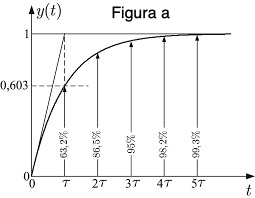 

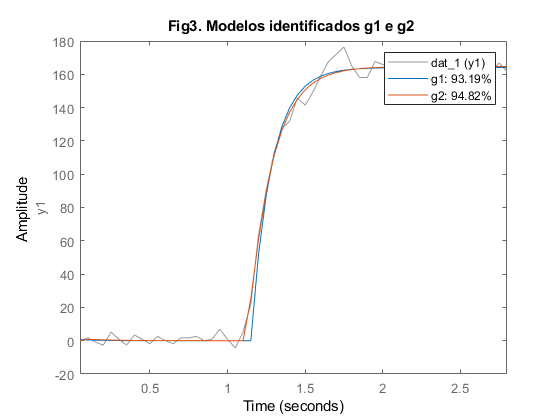

delay=0.05; 
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
g1=tfest(dat_1,1,0,delay);
g2=tfest(dat_1,2,0);
figure;compare(dat_1,g1,g2);title('Fig3. Modelos identificados g1 e g2 ');


g1=tf(g1.Numerator/g1.Denominator(2),g1.Denominator/g1.Denominator(2),'InputDelay',g1.IODelay)


g1 =
 
                    13.68
  exp(-0.05*s) * ------------
                 0.1307 s + 1
 
Continuous-time transfer function.



g2=tf(g2.Numerator,g2.Denominator)


g2 =
 
          3118
  ---------------------
  s^2 + 40.55 s + 227.1
 
Continuous-time transfer function.



K=freqresp(g2,0)

K = 13.7249

s0=stepinfo(g2)

s0 = struct with fields:
        RiseTime: 0.3384
    SettlingTime: 0.6157
     SettlingMin: 12.3744
     SettlingMax: 13.7133
       Overshoot: 0
      Undershoot: 0
            Peak: 13.7133
        PeakTime: 1.0861


## Atividade 3 - Projeto de um controlador PID via sintonia lambda

A Tabela abaixo mostra a sintonia $\lambda$ para controladores PI ou PID usando modelo de primeira ordem+tempo morto

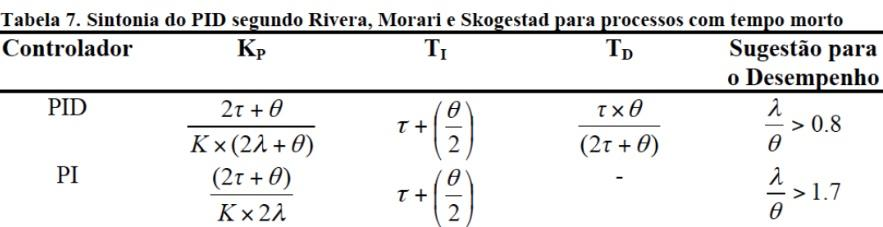

3.1 Sintonize os parâmetros de um controlador PI via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g1 para o projeto. Escolha $\lambda$ usando como referência a constante de tempo da atividade 2.2.

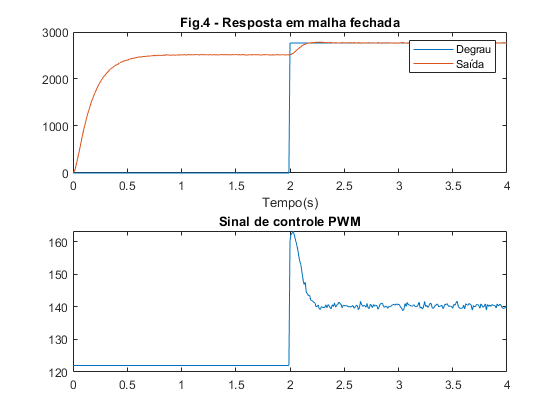

lambda=0.0735;
C=sintonia(g1,'PI','lam',lambda);

N=100;
kp=C.Kp;ki=C.Ki;kd=C.Kd;
Ts=0.01;
[Y,t]=simula_slx(arquivo,Tempo);

[erro,UP,SettlingTime, iae,G2] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);

figure;
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title('Fig.4 - Resposta em malha fechada');shg
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');

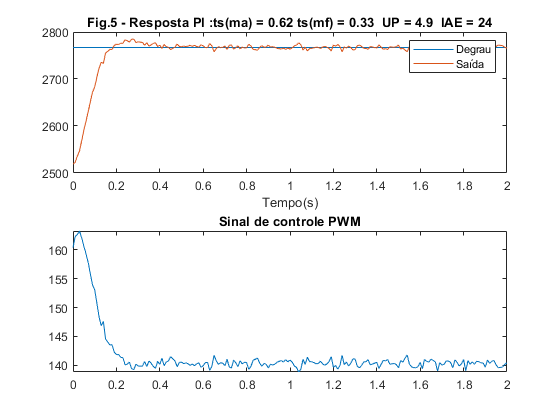


figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.5 - Resposta PI : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')

erro3=erro;
UP3=UP;
SettlingTime3=SettlingTime;
iae3=iae;

3.2 Sintonize os parametros de um controlador PID via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g1 para o projeto. 

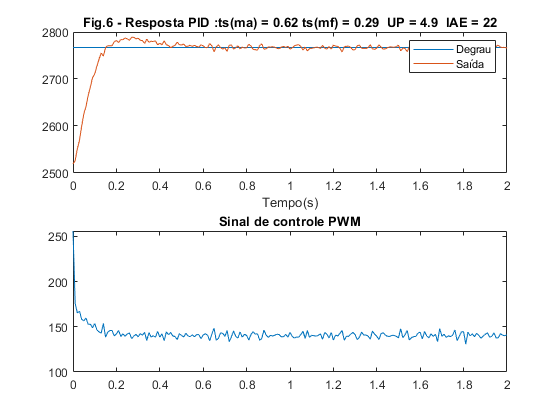

lambda=0.026;
C=sintonia(g1,'PID','lam',lambda);
kp=C.Kp;ki=C.Ki;kd=C.Kd;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UP,SettlingTime, iae] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);
figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.6 - Resposta PID : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')


erro3(2,1)=erro;
UP3(2,1)=UP;
SettlingTime3(2,1)=SettlingTime;
iae3(2,1)=iae;

A tabela abaixo mostra a sintonia de um controlador PID para um modelo de ordem 2 com polos complexos ou reais)

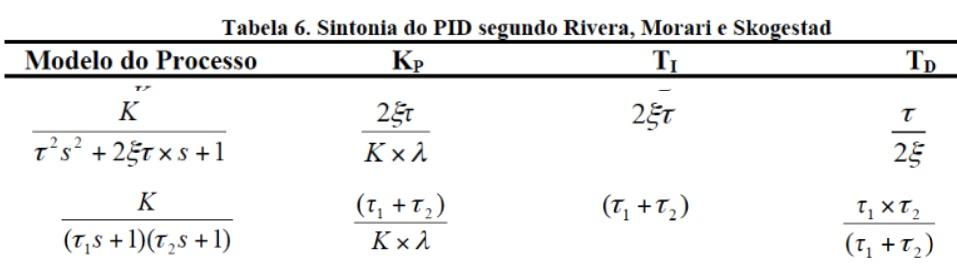

3.3 Sintonize os parametros de um controlador PID via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g2 para o projeto. 

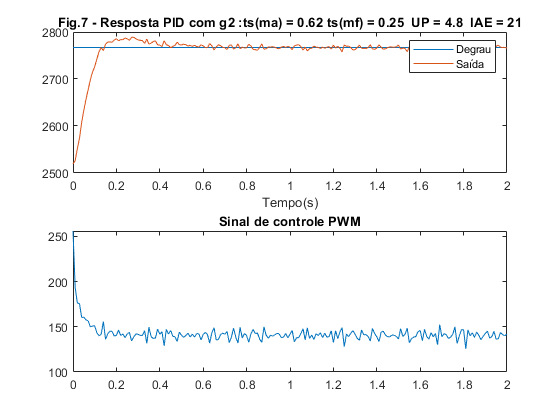

lambda=0.043;
C=sintonia(g2,[],'ordem2',lambda);
kp=C.Kp;ki=C.Ki;kd=C.Kd;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UP,SettlingTime, iae] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);
figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.7 - Resposta PID com g2 : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')


erro3(3)=erro;erro=erro3;
UP3(3)=UP;UP=UP3;
SettlingTime3(3)=SettlingTime;SettlingTime=SettlingTime3;
iae3(3)=iae; iae=iae3;
Metodos={'PI_g1';'PID_g1';'PID_g2'};
Tabela1=table(Metodos,erro,UP,SettlingTime,iae)

Tabela1 = 3×5 table
    Metodos       erro        UP      SettlingTime     iae  
    ________    ________    ______    ____________    ______

    'PI_g1'     0.012801    4.8574      0.32934       24.252
    'PID_g1'    0.012801     4.944      0.29067       22.261
    'PID_g2'    0.012801    4.7702      0.25418       20.949


3.4 Comente os valores de $\lambda$ usados nas 3 sintonias, justificando as escolhas. 

    Para todos os 3 casos, utilizamos como chute inicial o valor de tau que é a constante de tempo em malha aberta, assim fomos ajustando nosso  que é nossa constante de malha fechada para valores menores até que atendêssemos o melhor caso para nossos critérios de projeto.

    Dessa forma, para encontrar o melhor controlador, foi-se diminuindo $\lambda$, que por consequência aumentava o valor de Kp que deixa nossa resposta mais rápida, mas aumentando sobressinal. Assim, foi se diminuindo $\lambda$ de forma a se obter a resposta com menor tempo de estabelecimento possível sem ultrapassar nosso critério $UP\leq5\%$. Essa metodologia também nos gera o menor valor de IAE para os nossos critérios de projeto, uma vez que como visto em outros laboratórios, em geral a velocidade da resposta tem maior impacto no valor do IAE do que o sobressinal. 

    3.5 Qual o melhor controlador usando como critério o IAE e como critério UP e a tempo de estabelecimento?

   Analisando a tabela que foi gerada, como atingimos sobressinais parecidos, basta escolher o controlador que nos gera menor tempo de estabelecimento e menor IAE, que para o nosso caso, foi o controlador PID_g2 que apresentou o resultado mais desejável em todos os nossos parâmetros.

    Ainda observando a tabela, ao comparar o controlador PI com os outros dois, podemos perceber que os controladores PID em geral nos geram melhores parâmetros. Isso pode ser explicado pelo fato de que como visto nos laboratórios passados, a inserção do ganho derivativo Kd no nosso controlador diminui a sobrelevação, o que faz com que possamos obter valores ainda menores de $\lambda$ sem ultrapassar $UP\leq5\%$, o que nos permite reduzir ainda mais ts e IAE.

## Atividade 4 - Especificação de um modelo de referência no tempo

4.1 A partir do tempo de estabelecimento $t_s$ e da sobreelevação $UP$ obtidos com os controladores projetados, especifique um protótipo de segunda ordem $G(s)=\frac{w_n^2}{s(s+2\zeta w_n)}$ tal que sua resposta ao degrau em malha fechada de $M(s)=\frac{G(s)}{1+G(s)}$ seja semelhante à que foi obtida. Compare a resposta de $M(s)$ com a dos controladores sintonizados.

    A figura 8 representa a resposta ao degrau em malha fechada "ideal" para os parâmetros que obtivemos na síntese dos nossos controladores. Assim, comparando a figura 8 com as figuras 5,6 e 7 podemos perceber que nosso sistema com os respectivos controladores se aproxima bem da curva. O que podemos perceber de diferença, é o ruído presente no nosso sistema real, e a região de operação, onde nosso motor já se encontrava em uma velocidade e reponde a um pulso PWM como visto nos itens anteriores.

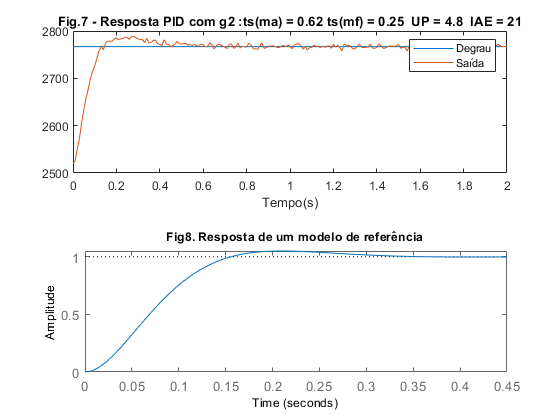

UP=5;
ts=0.28;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(ts*zeta);
m=tf(wn^2,[1 2*zeta*wn wn^2]);
step(m);title('Fig8. Resposta de um modelo de referência');


datetime('now')

ans = datetime
   06-Aug-2021 11:00:26


pwd

ans = 'C:\Users\asus1\Desktop\Faculdade\UFES\Materias\EAD\Lab de Controle\Aula7'